### Problem 1. Generate two sets of 1,000 random numbers that are drawn from the normal distribution. Create a scatter plot of the first set of numbers against the second set of numbers. Label the two axes as "Condition A" and "Condition B". Show the resulting figure.

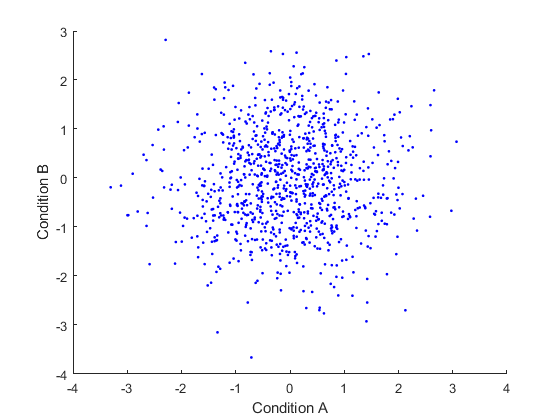


set1 = randn(1000,1);
set2 = randn(1000,1);
figure('Name', 'Problem 1'); hold on;
xlabel('Condition A')
ylabel('Condition B')
plot(set1, set2, 'b.')
hold off

### Problem 2. The data1 variable in Homework1.mat is a matrix of dimensions  2 x 20. Sum the numbers in each row and then compute the ratio between the two sums (i.e. sum of row 1 divided by sum of row 2). Store the answer in a variable called result and echo the value of this variable to the screen.


%Since MATLAB does not allow temporary array indexing, this anonymous function was
%implemented to access array indices in a rational way without declaring tons
%of variables
getRow = @(A, r) A(r,:);

file = matfile('D:\Src\Matlab\Statistical data analyze\Hometasks\Homework1.mat');
data1 = file.data1;
result = getRow(sum(data1,2),1)/getRow(sum(data1,2),2)

result = 0.4386

### Problem 3. The timeA, valsA, timeB, valsB variables in Homework1.mat represent time-series data for two signals, A and B. The time points at which A was measured are given in timeA, and the corresponding measurements are given in valsA. (The same goes for B, timeB, and valsB.) Create a  figure in which both signals are plotted as lines. Use a red line for A and a green line for B. Label the two axes and add a title and legend to the figure. Show the resulting figure.

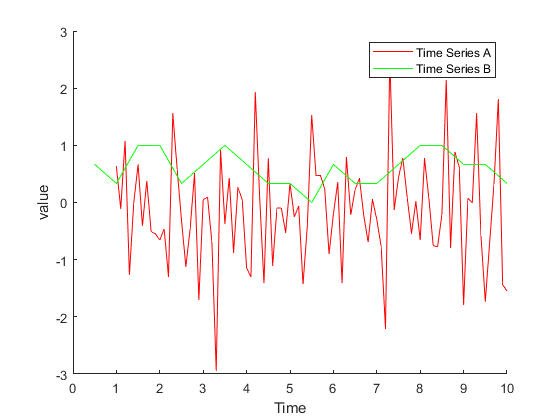


timeA = file.timeA;
timeB = file.timeB;
valsA = file.valsA;
valsB = file.valsB;
figure('Name', 'Problem 3'); hold on;
xlabel('Time')
ylabel('value')
plot(timeA, valsA, 'r-', 'DisplayName','Time Series A')
plot(timeB, valsB, 'g-', 'DisplayName','Time Series B')
legend; hold off;

### Problem 4. Create a variable containing the matrix shown to the right.

*(3 -1 1.5)*

*(2  0  0)*

*(1  1  1)*

### Then, append a new row to the matrix that consists of all 1s. Then, change the top-right element of the matrix to 0. Finally, extract the last column of the matrix and reshape it to be a row vector. Store this vector in a variable called result and echo the value of this variable to the screen.


matrix4 = [3, -1, 1.5; 2, 0, 0; 1, 1, 1];
matrix4 = [matrix4; 1, 1, 1];
matrix4(1, 3) = 0;
col = matrix4(:, end);
result = col.'

result =      0     0     1     1


### Problem 5. Write a function called checkpositive.m that accepts a 2D matrix as input and outputs a row vector. The row vector should contain as many elements as there are rows in the 2D matrix, and each element should indicate whether the corresponding row in the 2D matrix contains all positive numbers (use 0 to indicate no and 1 to indicate yes). The function should also report the results to the command window; the report should look something like this:

### Row 1: no Row 2: yes

### ...etc.


result = checkpositive([4 1 1; -1 0 0; 0 0 0; .1 .2 .1]);

Row 1: yes
Row 2: no
Row 3: no
Row 4: yes


result

result =      1     0     0     1


#### Function for the exercise 5:

function f = checkpositive(A) 
    result = zeros(1, length(A(:,1)));
    for i = 1:length(A(:,1))
        if any(A(i,:)>0) 
            result(1, i) = 1;
            fprintf('Row %u: yes\n', i);
        else
            fprintf('Row %u: no\n', i);
        end
    end
    f = result;
end
